Call the Summary Table

LatexPlots

% Load all data
load SummTableAG
filter = find(SummTable.hazlvl <= 6);
SummTable_AG = SummTable(filter, :);
load SummTable_OB
filter = find(SummTable.hazlvl <= 6);
SummTable_OB = SummTable(filter, :);
%filter = find((SummTable.hazlvl <= 3.0));
%SummTable = SummTable(filter, :)

Plot of PGA vs Derailments

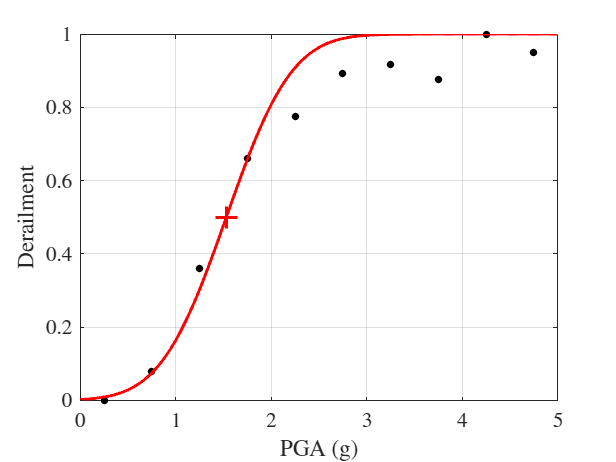

NotSortedData = [SummTable_OB.pga/9.81, SummTable_OB.drcase];
SortedData = sortrows(NotSortedData);
win_size = 0.5;

im = zeros(1, 5/win_size + 1);
num_gms = zeros(1, 5/win_size + 1);
num_collapse = zeros(1, 5/win_size + 1);

ii = 0;

for pga_vals = 0:win_size:5
    ii = ii + 1;
    pga_min = pga_vals;
    pga_max = pga_vals + win_size;
    idx = find((SortedData(:, 1) > pga_min).*(SortedData(:, 1) < pga_max));

    im(ii) = 0.5 * (pga_max + pga_min);
    num_collapse(ii) = sum(SortedData(idx, 2));
    num_gms(ii) = length(idx);
end

[theta, beta] = fn_mle_pc(im, num_gms, num_collapse);

xnew = 0:0.01:5;
ynew = normcdf(xnew, theta, beta);

figure(1)
plot(im, num_collapse./num_gms, 'k.', ...
    [theta], [0.5], 'r+', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0, 'LineWidth', 2.0), fontsize(14, 'points'), grid on, xlabel('PGA (g)'), ylabel('Derailment')

% PCHA Fragility

NotSortedData = [SummTable_OB.pcha/9.81, SummTable_OB.drcase];
SortedData = sortrows(NotSortedData);

win_size = 0.05;
im_max = 0.5;

im = zeros(1, im_max/win_size + 1);
num_gms = zeros(1, im_max/win_size + 1);
num_collapse = zeros(1, im_max/win_size + 1);

ii = 0;

for pga_vals = 0:win_size:im_max
    ii = ii + 1;
    pga_min = pga_vals;
    pga_max = pga_vals + win_size;
    idx = find((SortedData(:, 1) > pga_min).*(SortedData(:, 1) < pga_max));

    im(ii) = 0.5 * (pga_max + pga_min);
    num_collapse(ii) = sum(SortedData(idx, 2));
    num_gms(ii) = length(idx);
end

[theta, beta] = fn_mle_pc(im, num_gms, num_collapse)

theta = 0.4710

beta = 0.2167

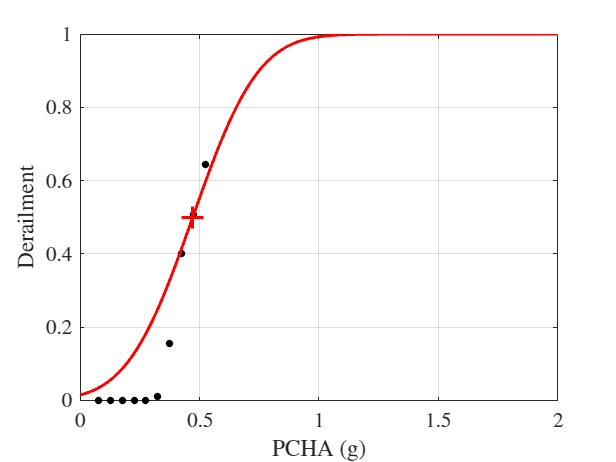

xnew = 0:0.01:2;
ynew = normcdf(xnew, theta, beta);

figure()
plot(im, num_collapse./num_gms, 'k.', ...
    [theta], [0.5], 'r+', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0, 'LineWidth', 2.0), fontsize(14, 'points'), grid on, xlabel('PCHA (g)'), ylabel('Derailment')

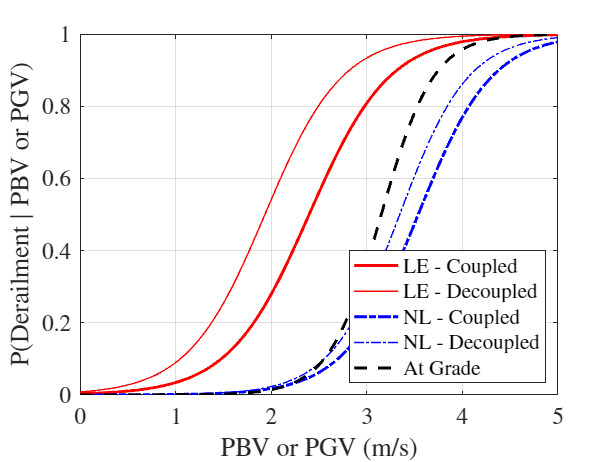


%% LINEAR ELASTIC MODEL
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot LE model
plot(...
    xnew, ynew, 'r', 'LineWidth', 2.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

% Decoupled case now
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot LE model - decoupled
plot(...
    xnew, ynew, 'r', 'LineWidth', 1.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on
%%%%%

% NONLINEAR MODEL
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot NL Model
plot(...
    xnew, ynew, 'b-.', 'linewidth', 2.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])

% Decoupled
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot NL Model
plot(...
    xnew, ynew, 'b-.', 'linewidth', 1.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])
%

% AT GRADE MODEL
filter = find((SummTable_AG.bridgemodel == 1.0) .* (SummTable_AG.cf == 1.0));
NotSortedData = [SummTable_AG(filter,:).pgv, SummTable_AG(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot At Grade Model
fontsize(16, 'points')
plot(...
    xnew, ynew, 'k--', 'linewidth', 2.0), grid on, xlabel('PBV or PGV (m/s)'), ylabel('P(Derailment $|$ PBV or PGV)'), xlim([0 5])
legend('LE - Coupled', 'LE - Decoupled', 'NL - Coupled', 'NL - Decoupled', 'At Grade', 'location', 'southeast')

%saveas(gcf, 'frag_pbv_pgv.pdf')

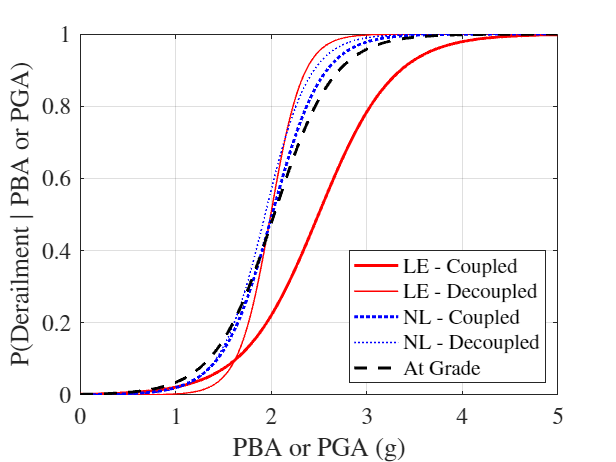

close
% LINEAR ELASTIC MODEL
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pba/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(...
    xnew, ynew, 'r', 'LineWidth', 2.0), grid on, xlabel('PBA (g)'), ylabel('Derailment')
hold on

% Decoupled
% LINEAR ELASTIC MODEL
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pba/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(...
    xnew, ynew, 'r', 'LineWidth', 1.0), grid on, xlabel('PBA (g)'), ylabel('Derailment')
hold on

%NONLINEAR MODEL
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pba/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(...
    xnew, ynew, 'b:', 'LineWidth', 2.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])

% Decoupled
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pba/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(...
    xnew, ynew, 'b:', 'LineWidth', 1.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])

% NOW, DO AT GRADE
filter = find((SummTable_AG.bridgemodel == 1.0) .* (SummTable_AG.cf == 1.0));
NotSortedData = [SummTable_AG(filter,:).pga/9.81, SummTable_AG(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Linear Model
fontsize(16, 'points')
plot(...
    xnew, ynew, 'k--', 'LineWidth', 2.0), grid on, xlabel('PBA or PGA (g)'), ylabel('P(Derailment $|$ PBA or PGA)'), xlim([0 5])
legend('LE - Coupled', 'LE - Decoupled', 'NL - Coupled', 'NL - Decoupled', 'At Grade', 'location', 'southeast')

% saveas(gcf, 'frag_pba_pga.pdf')

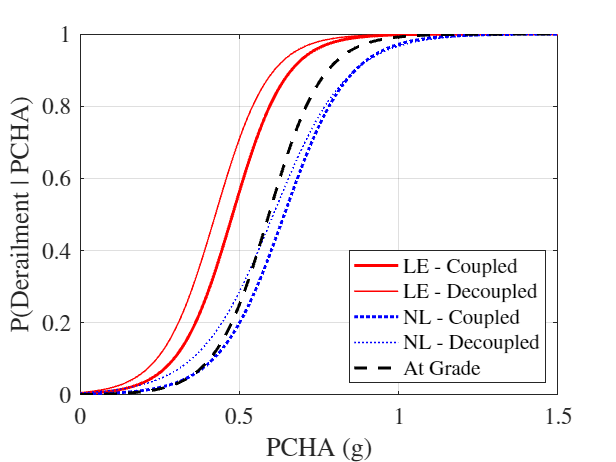

close
% LINEAR ELASTIC MODEL
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pcha/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(...
    xnew, ynew, 'r', 'LineWidth', 2.0), grid on, xlabel('PBA (g)'), ylabel('Derailment')
hold on

% Decoupled
% LINEAR ELASTIC MODEL
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pcha/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(...
    xnew, ynew, 'r', 'LineWidth', 1.0), grid on, xlabel('PBA (g)'), ylabel('Derailment')
hold on

%NONLINEAR MODEL
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pcha/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(...
    xnew, ynew, 'b:', 'LineWidth', 2.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])

% Decoupled
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pcha/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(...
    xnew, ynew, 'b:', 'LineWidth', 1.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])

% NOW, DO AT GRADE
filter = find((SummTable_AG.bridgemodel == 1.0) .* (SummTable_AG.cf == 1.0));
NotSortedData = [SummTable_AG(filter,:).pcha/9.81, SummTable_AG(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Linear Model
fontsize(16, 'points')
plot(...
    xnew, ynew, 'k--', 'LineWidth', 2.0), grid on, xlabel('PCHA (g)'), ylabel('P(Derailment | PCHA)'), xlim([0 1.5])
legend('LE - Coupled', 'LE - Decoupled', 'NL - Coupled', 'NL - Decoupled', 'At Grade', 'location', 'southeast')

% saveas(gcf, 'frag_pcha.pdf')

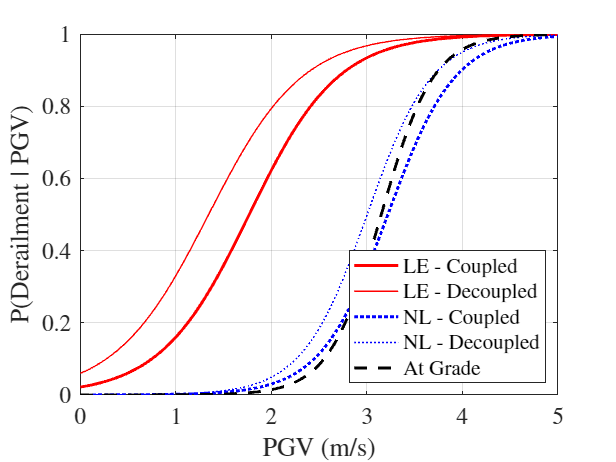

close
% LINEAR ELASTIC MODEL
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pgv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot LE model
plot(...
    xnew, ynew, 'r', 'LineWidth', 2.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

% Decoupled case now
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pgv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot LE model - decoupled
plot(...
    xnew, ynew, 'r', 'LineWidth', 1.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on
%%%%%

% NONLINEAR MODEL
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pgv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot NL Model
plot(...
    xnew, ynew, 'b:', 'linewidth', 2.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])

% Decoupled
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pgv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot NL Model
plot(...
    xnew, ynew, 'b:', 'linewidth', 1.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])
%

% AT GRADE MODEL
filter = find((SummTable_AG.bridgemodel == 1.0) .* (SummTable_AG.cf == 1.0));
NotSortedData = [SummTable_AG(filter,:).pgv, SummTable_AG(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot At Grade Model
fontsize(16, 'points')
plot(...
    xnew, ynew, 'k--', 'linewidth', 2.0), grid on, xlabel('PGV (m/s)'), ylabel('P(Derailment | PGV)'), xlim([0 5])
legend('LE - Coupled', 'LE - Decoupled', 'NL - Coupled', 'NL - Decoupled', 'At Grade', 'location', 'southeast')

% saveas(gcf, 'frag_pgv.pdf')


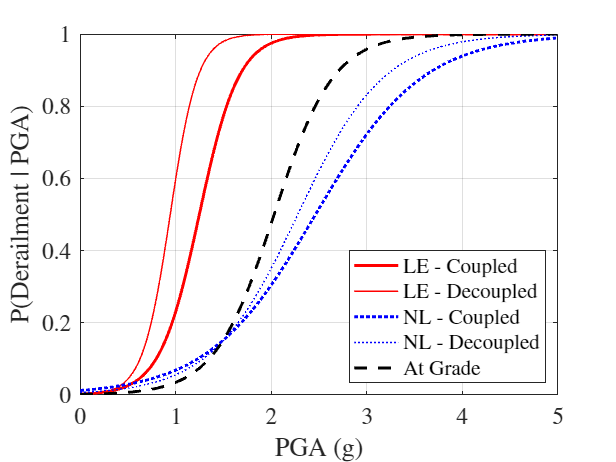


close
% LINEAR ELASTIC MODEL
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pga/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot LE model
plot(...
    xnew, ynew, 'r', 'LineWidth', 2.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

% Decoupled case now
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pga/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot LE model - decoupled
fontsize(16, 'points')
plot(...
    xnew, ynew, 'r', 'LineWidth', 1.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on
%%%%%

% NONLINEAR MODEL
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pga/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot NL Model
plot(...
    xnew, ynew, 'b:', 'linewidth', 2.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])

% Decoupled
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pga/9.81, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot NL Model
plot(...
    xnew, ynew, 'b:', 'linewidth', 1.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])
%

% AT GRADE MODEL
filter = find((SummTable_AG.bridgemodel == 1.0) .* (SummTable_AG.cf == 1.0));
NotSortedData = [SummTable_AG(filter,:).pga/9.81, SummTable_AG(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot At Grade Model
fontsize(16, 'points')
plot(...
    xnew, ynew, 'k--', 'linewidth', 2.0), grid on, xlabel('PGA (g)'), ylabel('P(Derailment | PGA)'), xlim([0 5])
legend('LE - Coupled', 'LE - Decoupled', 'NL - Coupled', 'NL - Decoupled', 'At Grade', 'location', 'southeast')

% saveas(gcf, 'frag_pga.pdf')

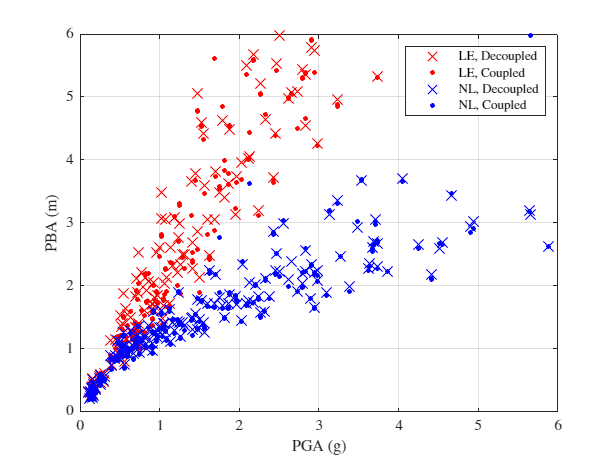

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

fontsize(16, 'points')
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBA (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 6, 0, 6])
grid on

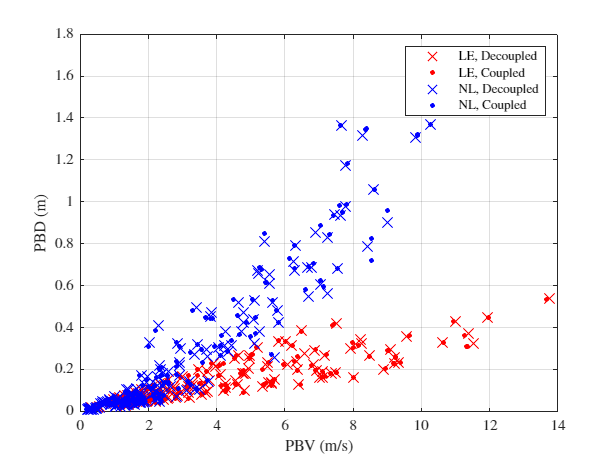

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

fontsize(16, 'points')
plot(SummTable(indices1,:).pbv, SummTable(indices1,:).pbd, 'rx', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).pbd, 'r.', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).pbd, 'bx', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).pbd, 'b.','MarkerSize', 10.0)

xlabel('PBV (m/s)'), ylabel('PBD (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

%axis([0, 3, 0, 3])
grid on

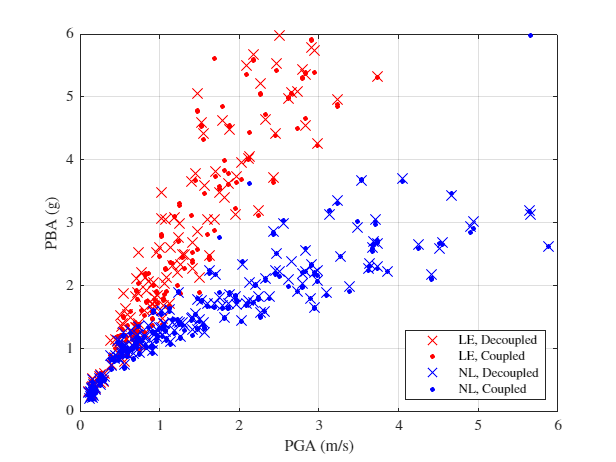

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

fontsize(16, 'points')
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PGA (m/s)'), ylabel('PBA (g)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled', 'location', 'southeast')

axis([0, 6, 0, 6])
grid on

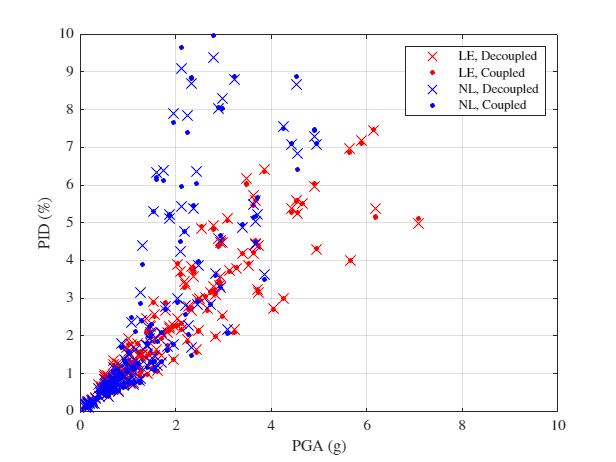

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

fontsize(16, 'points')
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pbd / 6 * 100, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pbd / 6 * 100, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pbd / 6 * 100, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pbd / 6 * 100, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PID (\%)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 10, 0, 10])
grid on

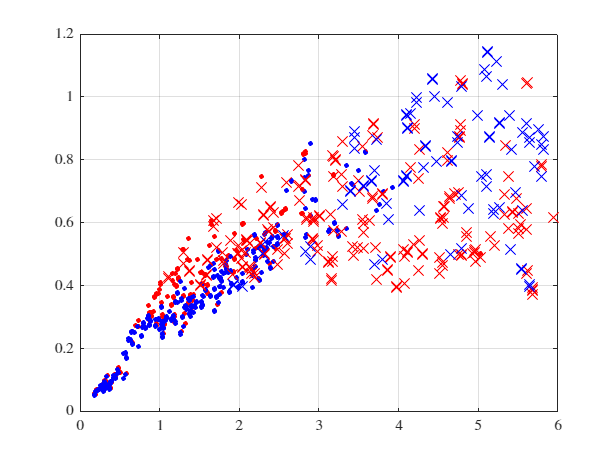

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0));  % Nonlinear, Coupled

fontsize(16, 'points')
plot(SummTable(indices1,:).pbv, SummTable(indices1,:).pcha/9.81, 'r.', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).pcha/9.81, 'b.', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).pcha/9.81, 'rx', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).pcha/9.81, 'bx','MarkerSize', 10.0)
axis([0 6 0 1.2])
grid on

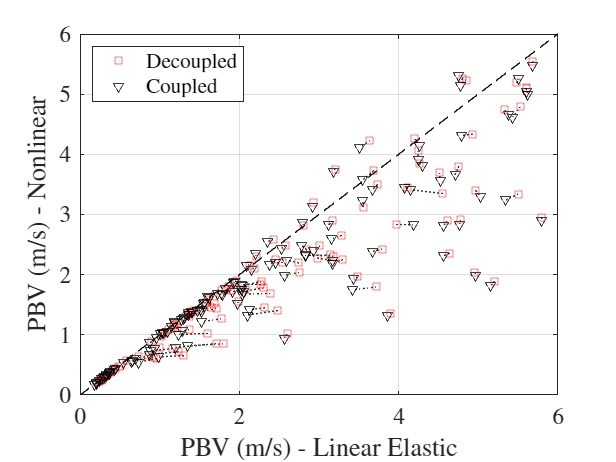

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0).*(SummTable.spd > 20.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0).*(SummTable.spd > 20.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0).*(SummTable.spd > 20.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0).*(SummTable.spd > 20.0));  % Nonlinear, Coupled

for i = 1:length(indices1)
    plot([SummTable(indices1(i),:).pbv, SummTable(indices3(i),:).pbv], ...
         [SummTable(indices2(i),:).pbv, SummTable(indices4(i),:).pbv], ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

fontsize(16, 'points')
plot(SummTable(indices1,:).pbv, SummTable(indices2,:).pbv, 'rs', ...
     SummTable(indices3,:).pbv, SummTable(indices4,:).pbv, 'kv', ...
     [0 10], [0 10], 'k--', 'MarkerSize', 6.0), grid
axis([0 6 0 6])
xlabel('PBV (m/s) - Linear Elastic')
ylabel('PBV (m/s) - Nonlinear')
legend('Decoupled', 'Coupled', 'location', 'northwest')

saveas(gcf, 'pbv_linear_nonlinear.pdf')

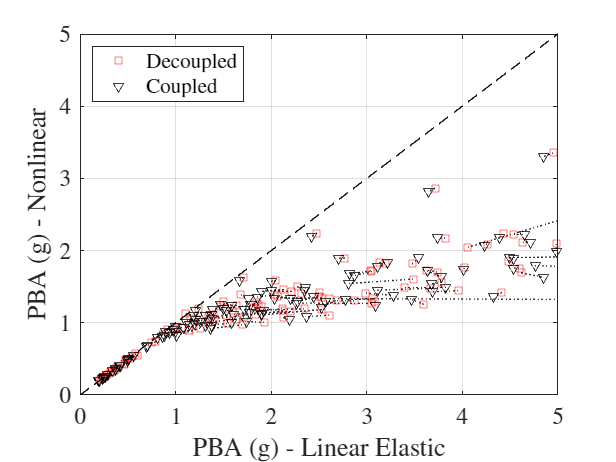


close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0).*(SummTable.spd > 20.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0).*(SummTable.spd > 20.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0).*(SummTable.spd > 20.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0).*(SummTable.spd > 20.0));  % Nonlinear, Coupled

for i = 1:length(indices1)
    plot([SummTable(indices1(i),:).pba, SummTable(indices3(i),:).pba]/9.81, ...
         [SummTable(indices2(i),:).pba, SummTable(indices4(i),:).pba]/9.81, ':', ...
        linewidth=0.5, HandleVisibility='off', Color=[0.2, 0.2, 0.2]), hold on
end

fontsize(16, 'points')
plot(SummTable(indices1,:).pba/9.81, SummTable(indices2,:).pba/9.81, 'rs', ...
     SummTable(indices3,:).pba/9.81, SummTable(indices4,:).pba/9.81, 'kv', ...
     [0 10], [0 10], 'k--', 'MarkerSize', 6.0), grid
axis([0 5 0 5])
xlabel('PBA (g) - Linear Elastic')
ylabel('PBA (g) - Nonlinear')
legend('Decoupled', 'Coupled', 'location', 'northwest')

saveas(gcf, 'pba_linear_nonlinear.pdf')

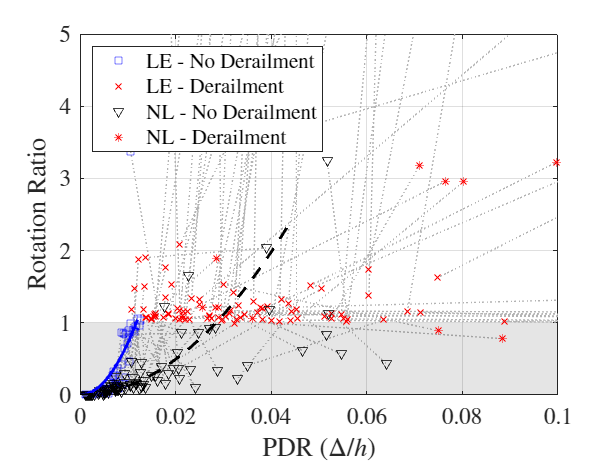

close all
cfac = 1.0;
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear, Coupled

indices5 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));


peakrot = 0.836;

pfit1 = fit(SummTable(indices1,:).pbd/6, SummTable(indices1,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable(indices3,:).pbd/6, SummTable(indices3,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable(indices5(i),:).pbd, SummTable(indices6(i),:).pbd] / 6, [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.7, 0.7, 0.7]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')
plot(SummTable(indices1,:).pbd/6, SummTable(indices1,:).purot/peakrot, 'bs', ...
     SummTable(indices2,:).pbd/6, SummTable(indices2,:).purot/peakrot, 'rx', ...
     SummTable(indices3,:).pbd/6, SummTable(indices3,:).purot/peakrot, 'kv', ...
     SummTable(indices4,:).pbd/6, SummTable(indices4,:).purot/peakrot, 'r*', 'MarkerSize', 6.0)

fontsize(16, 'points')
plot(0:0.001:0.012, pfit1(0:0.001:0.012)/peakrot, 'b', ...
     0:0.001:0.044, pfit2(0:0.001:0.044)/peakrot, 'k--', ...
     'LineWidth', 2.0);

axis([0 0.1 0 5.0])
grid, legend('LE - No Derailment', 'LE - Derailment', 'NL - No Derailment', 'NL - Derailment', Location='northwest')
xlabel('PDR ($\Delta / h$)'), ylabel('Rotation Ratio')

% saveas(gcf, 'rr_pdr.pdf')

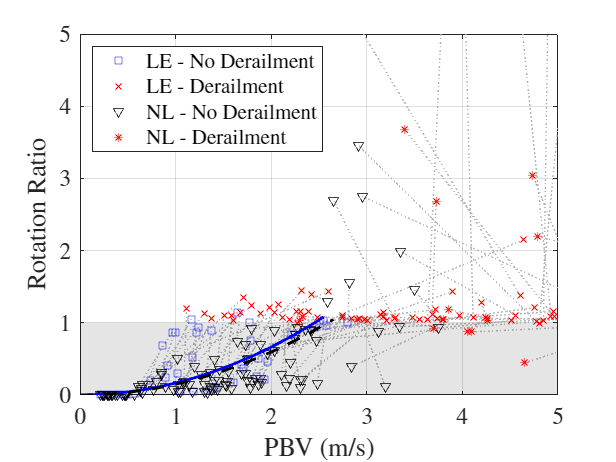

close all
cfac = 0.0;
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear, Coupled

indices5 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));


peakrot = 0.836;

pfit1 = fit(SummTable(indices1,:).pbv, SummTable(indices1,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable(indices3,:).pbv, SummTable(indices3,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable(indices5(i),:).pbv, SummTable(indices6(i),:).pbv], ...
         [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.7, 0.7, 0.7]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')
plot(SummTable(indices1,:).pbv, SummTable(indices1,:).purot/peakrot, 'bs', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).purot/peakrot, 'rx', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).purot/peakrot, 'kv', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).purot/peakrot, 'r*', 'MarkerSize', 6.0)

fontsize(16, 'points')
plot(0:0.01:2.55, pfit1(0:0.01:2.55)/peakrot, 'b', ...
     0:0.01:2.65, pfit2(0:0.01:2.65)/peakrot, 'k--', ...
     'LineWidth', 2.0);
axis([0 5.0 0 5.0])
grid, legend('LE - No Derailment', 'LE - Derailment', 'NL - No Derailment', 'NL - Derailment', Location='northwest')
xlabel('PBV (m/s)'), ylabel('Rotation Ratio')

% saveas(gcf, 'rr_pbv_model.pdf')

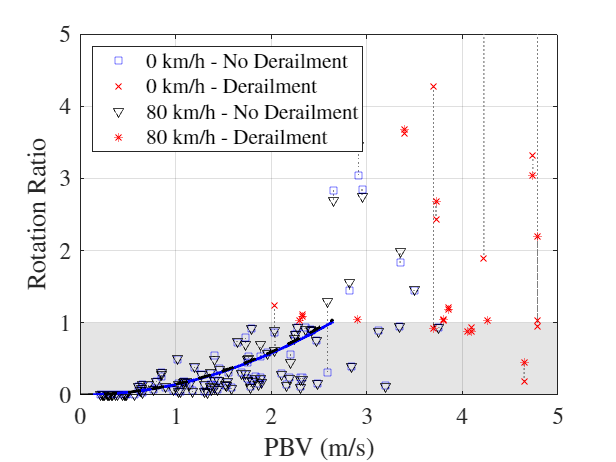

close all
cfac = 0.0;  % Only coupled cases
indices1 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Linear No derail
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Linear Derail
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear No derail
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear derail

indices5 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Nonlinear, all
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear, all

peakrot = 0.836;

pfit1 = fit(SummTable(indices1,:).pbv, SummTable(indices1,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable(indices3,:).pbv, SummTable(indices3,:).purot, fittype({'x^2'}));

for i = 1:length(indices5)
    plot([SummTable(indices5(i),:).pbv, SummTable(indices6(i),:).pbv], [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.5, 0.5, 0.5]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')
plot(SummTable(indices1,:).pbv, SummTable(indices1,:).purot/peakrot, 'bs', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).purot/peakrot, 'rx', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).purot/peakrot, 'kv', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).purot/peakrot, 'r*', 'MarkerSize', 6.0)

fontsize(16, 'points')
plot(0:0.01:2.65, pfit1(0:0.01:2.65)/peakrot, 'b', ...
     0:0.01:2.65, pfit2(0:0.01:2.65)/peakrot, 'k--', ...
     'LineWidth', 2.0);

axis([0 5.0 0 5.0])
grid, legend('0 km/h - No Derailment', '0 km/h - Derailment', '80 km/h  - No Derailment', '80 km/h  - Derailment', Location='northwest')
xlabel('PBV (m/s)'), ylabel('Rotation Ratio')

% saveas(gcf, 'rr_pbv_spd_dec.pdf')

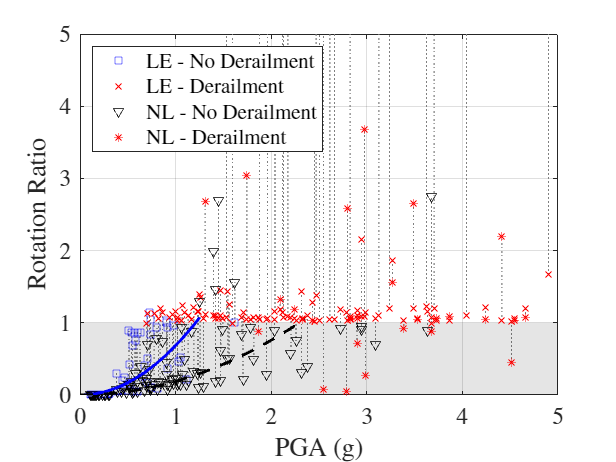

close all
cfac = 0.0;  % Only coupled cases
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear No derail
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear Derail
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear No derail
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear derail

indices5 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear, all
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear, all

peakrot = 0.836;

pfit1 = fit(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable(indices3,:).pga/9.81, SummTable(indices3,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable(indices5(i),:).pga, SummTable(indices6(i),:).pga]/9.81, [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.5, 0.5, 0.5]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

fontsize(16, 'points')
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).purot/peakrot, 'bs', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).purot/peakrot, 'rx', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).purot/peakrot, 'kv', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).purot/peakrot, 'r*', 'MarkerSize', 6.0)
plot(0:0.01:1.25, pfit1(0:0.01:1.25)/peakrot, 'b', ...
     0:0.01:2.35, pfit2(0:0.01:2.35)/peakrot, 'k--', ...
     'LineWidth', 2.0);

axis([0 5.0 0 5.0])
grid, legend('LE - No Derailment', 'LE - Derailment', 'NL - No Derailment', 'NL - Derailment', Location='northwest')
xlabel('PGA (g)'), ylabel('Rotation Ratio')

% saveas(gcf, 'rr_pga_model.pdf')

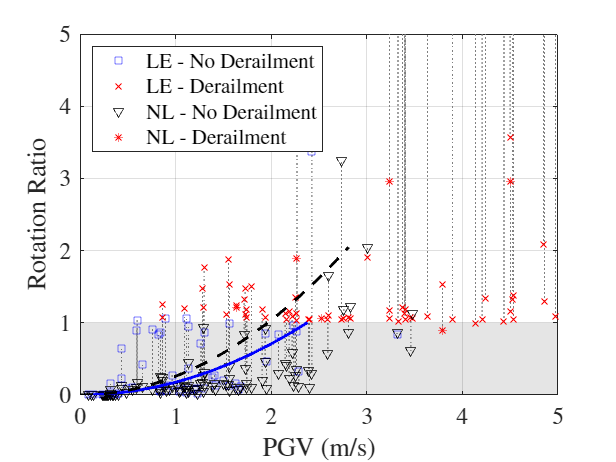

close all
cfac = 1.0;  % Only coupled cases
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear No derail
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear Derail
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear No derail
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear derail

indices5 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Nonlinear, all
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 1));  % Linear, all

peakrot = 0.836;

pfit1 = fit(SummTable(indices1,:).pgv, SummTable(indices1,:).purot, fittype({'x^2'}));
pfit2 = fit(SummTable(indices3,:).pgv, SummTable(indices3,:).purot, fittype({'x^2'}));

for i = 1:length(indices6)
    plot([SummTable(indices5(i),:).pgv, SummTable(indices6(i),:).pgv], ...
        [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.5, 0.5, 0.5]), hold on
end

area(0:0.01:6.0, ones(1, length(0:0.01:6.0)),'FaceAlpha', 0.1, 'FaceColor', 'k', 'EdgeColor', 'none', 'HandleVisibility','off')

plot(SummTable(indices1,:).pgv, SummTable(indices1,:).purot/peakrot, 'bs', ...
     SummTable(indices2,:).pgv, SummTable(indices2,:).purot/peakrot, 'rx', ...
     SummTable(indices3,:).pgv, SummTable(indices3,:).purot/peakrot, 'kv', ...
     SummTable(indices4,:).pgv, SummTable(indices4,:).purot/peakrot, 'r*', 'MarkerSize', 6.0)

fontsize(16, 'points')
plot(0:0.01:2.38, pfit1(0:0.01:2.38)/peakrot, 'b', ...
     0:0.01:2.81, pfit2(0:0.01:2.81)/peakrot, 'k--', ...
     'LineWidth', 2.0);

axis([0 5.0 0 5.0])
grid, legend('LE - No Derailment', 'LE - Derailment', 'NL - No Derailment', 'NL - Derailment', Location='northwest')
xlabel('PGV (m/s)'), ylabel('Rotation Ratio')

% saveas(gcf, 'rr_pgv_model.pdf')

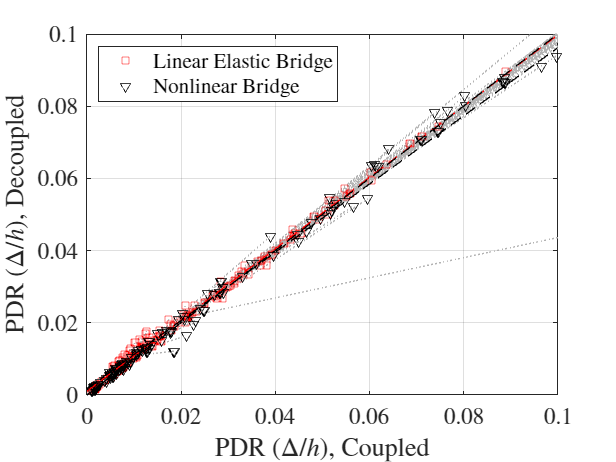

% Coupled/Decoupled 
close all
indices1 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices2 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled
indices3 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices4 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled


reg1 = polyfit(SummTable(indices1,:).pbd/6, SummTable(indices3,:).pbd/6, 1);
reg2 = polyfit(SummTable(indices2,:).pbd/6, SummTable(indices4,:).pbd/6, 1);

for i = 1:length(indices6)
    plot([SummTable(indices1(i),:).pbd/6, SummTable(indices2(i),:).pbd/6], ...
         [SummTable(indices3(i),:).pbd/6, SummTable(indices4(i),:).pbd/6], ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.7, 0.7, 0.7]), hold on
end

xmax = 0.1;
fontsize(16, 'points')
plot(SummTable(indices1,:).pbd/6, SummTable(indices3,:).pbd/6, 'rs', ...
     SummTable(indices2,:).pbd/6, SummTable(indices4,:).pbd/6, 'kv', ...
     [0, xmax], polyval(reg1, [0,xmax]), 'r--', ...
     [0, xmax], polyval(reg2, [0,xmax]), 'k--', ...
     [0, xmax], [0, xmax], 'k--', MarkerSize=6.0), axis([0 xmax 0 xmax]),...
xlabel('PDR ($\Delta/h$), Coupled'), ylabel('PDR ($\Delta/h$), Decoupled'), grid on,...
legend('Linear Elastic Bridge', 'Nonlinear Bridge', Location='northwest')

% saveas(gcf, 'pdr_coupled_model.pdf')

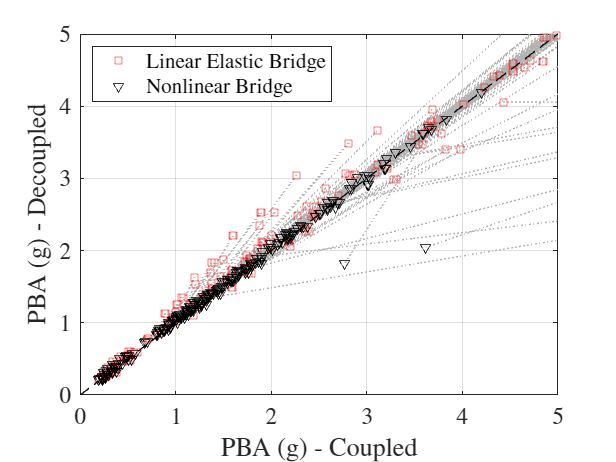

close all
indices1 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 0.0));  % Coupled, Linear
indices2 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 1.0));  % Coupled, Nonlinear
indices3 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 0.0));  % Decoupled, Linear
indices4 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled, Nonlinear


reg1 = polyfit(SummTable(indices1,:).pba/9.81, SummTable(indices3,:).pba/9.81, 1);
reg2 = polyfit(SummTable(indices2,:).pba/9.81, SummTable(indices4,:).pba/9.81, 1);

for i = 1:length(indices1)
    plot([SummTable(indices1(i),:).pba, SummTable(indices2(i),:).pba]/9.81, ...
         [SummTable(indices3(i),:).pba, SummTable(indices4(i),:).pba]/9.81, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.7, 0.7, 0.7]), hold on
end

fontsize(16, 'points')
plot(SummTable(indices1,:).pba/9.81, SummTable(indices3,:).pba/9.81, 'rs', ...
     SummTable(indices2,:).pba/9.81, SummTable(indices4,:).pba/9.81, 'kv', ...
     [0, 5], [0, 5], 'k--', MarkerSize=6.0), axis([0 5.0 0 5.0]), ...
     xlabel('PBA (g) - Coupled'), ylabel('PBA (g) - Decoupled'), grid on, ...
     legend('Linear Elastic Bridge', 'Nonlinear Bridge', Location='northwest')

% saveas(gcf, 'pba_coupled_model.pdf')

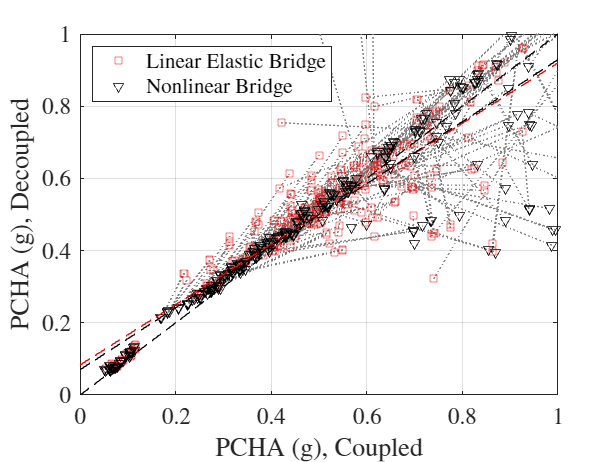

close all
SummTable = SummTable_OB;
indices1 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices2 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled
indices3 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices4 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled


reg1 = polyfit(SummTable(indices1,:).pcha / 9.81, SummTable(indices3,:).pcha / 9.81, 1);
reg2 = polyfit(SummTable(indices2,:).pcha / 9.81, SummTable(indices4,:).pcha / 9.81, 1);

for i = 1:length(indices4)
    plot([SummTable(indices1(i),:).pcha, SummTable(indices2(i),:).pcha]/9.81, ...
         [SummTable(indices3(i),:).pcha, SummTable(indices4(i),:).pcha]/9.81, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.5, 0.5, 0.5]), hold on
end

fontsize(16, 'points')
plot(SummTable(indices1,:).pcha / 9.81, SummTable(indices3,:).pcha / 9.81, 'rs', ...
     SummTable(indices2,:).pcha / 9.81, SummTable(indices4,:).pcha / 9.81, 'kv', ...
     [0, 1], polyval(reg1, [0,1]), 'r--', ...
     [0, 1], polyval(reg2, [0,1]), 'k--', ...
     [0, 1], [0, 1], 'k--', MarkerSize=6.0), axis([0 1 0 1]), ...
     xlabel('PCHA (g), Coupled'), ylabel('PCHA (g), Decoupled'), grid on, ...
     legend('Linear Elastic Bridge', 'Nonlinear Bridge', Location='northwest')

% saveas(gcf, 'pcha_coupled_model.pdf')






















